%https://www.electrical4u.com/magnetic-reluctance/
clear
filename = 'design_params_ref.xlsx';
[NUM,TXT,RAW] = xlsread(filename);
PI = pi;
for i=1:size(RAW,1)
    eval(RAW(i,1) + " = " + RAW(i,2) + ";")
    eval("valve." + RAW(i,1) + " = " + RAW(i,1) + ";")
end
clearvars -except valve

## Modification

## Sealin Surface

do = 0.5;
r = 0.25;
R = 0.5 * do + r;
fun = @(x) 2*pi*(sqrt(r^2 - x.^2) + R).*sqrt(r^2./(r^2 - x.^2))

fun = function_handle with value:
    @(x)2*pi*(sqrt(r^2-x.^2)+R).*sqrt(r^2./(r^2-x.^2))


S = integral(fun,0,r)

S = 1.6264

Ao = pi * do^2 / 4

Ao = 0.1963

Ap = pi * R^2

Ap = 0.7854

20.5*S

ans = 33.3412

50*Ap

ans = 39.2699

## Magnetic Reluctance

rel_perm = 850

rel_perm = 850

air_perm = 1.25663753*1e-6

air_perm = 1.2566e-06

valve.perm = rel_perm * air_perm

valve = struct with fields:
                                  rom: 0.2500
                            clearance: 0.1000
                              oring_d: 1.7800
               face_oring_gland_depth: 1.3400
              face_oring_groove_width: 2.1500
                      face_oring_dout: 12.8100
                  oring_groove_radius: 0.2000
             radial_oring_gland_depth: 1.2900
            radial_oring_groove_width: 2.3500
                    radial_oring_dout: 20.7300
          valve_seat_outlet_orifice_d: 0.5000
        valve_seat_outlet_orifice_rad: 0.5000
                  valve_seat_outlet_d: 22
                  valve_seat_outlet_h: 3
    valve_seat_outlet_face_oring_dout: 12.8100
     valve_seat_outlet_face_oring_din: 8.5100
       valve_seat_outlet_face_oring_h: 1.3400
                   valve_seat_inlet_h: 3
                   valve_seat_upper_h: 5
     valve_seat_upper_face_oring_dout: 12.8100
      valve_seat_upper_face_oring_din: 8.5100
        valve_seat_up

wire_areas = [0.032 0.05 0.1 0.2 0.4 0.7 1]; %mm^2
rec_max_A = 3.5; % A/mm2;
for i=1:length(wire_areas)
    valve.wire_area = wire_areas(i);
    [Fmag(i),N(i),wire_len(i),wire_R(i),sol_V(i),sol_P(i),L(i)] = valve_magnetic_force(valve,valve.rom,rec_max_A * valve.wire_area);
end
Fmag

Fmag =    46.4806   46.4806   46.4806   46.4806   46.4806   46.4806   46.4806


plot(wire_areas,L./wire_R), xlabel('Wire cross section [mm^2]'), ylabel('Tao [s]')

semilogy(wire_areas,L), xlabel('Wire cross section [mm^2]'), ylabel('Inductance [H]')

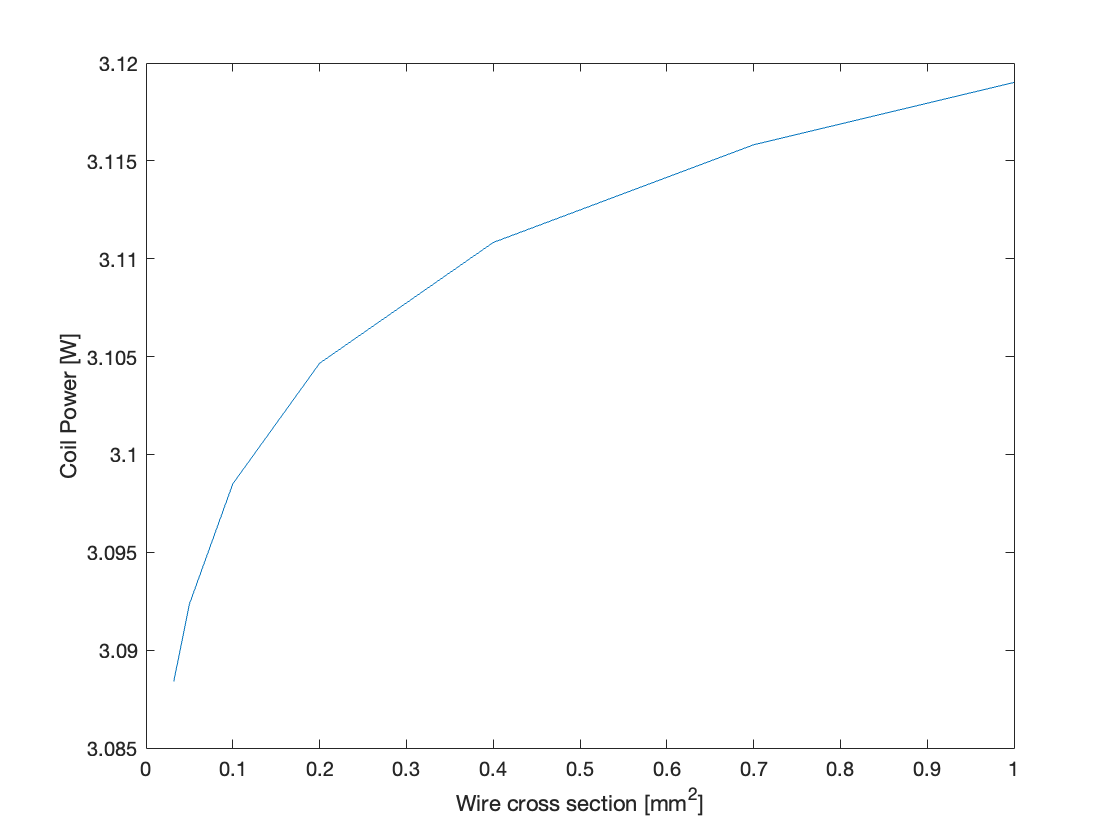

plot(wire_areas,sol_P), xlabel('Wire cross section [mm^2]'), ylabel('Coil Power [W]')

plot(wire_areas,sol_V), xlabel('Wire cross section [mm^2]'), ylabel('Coil Voltage [V]')

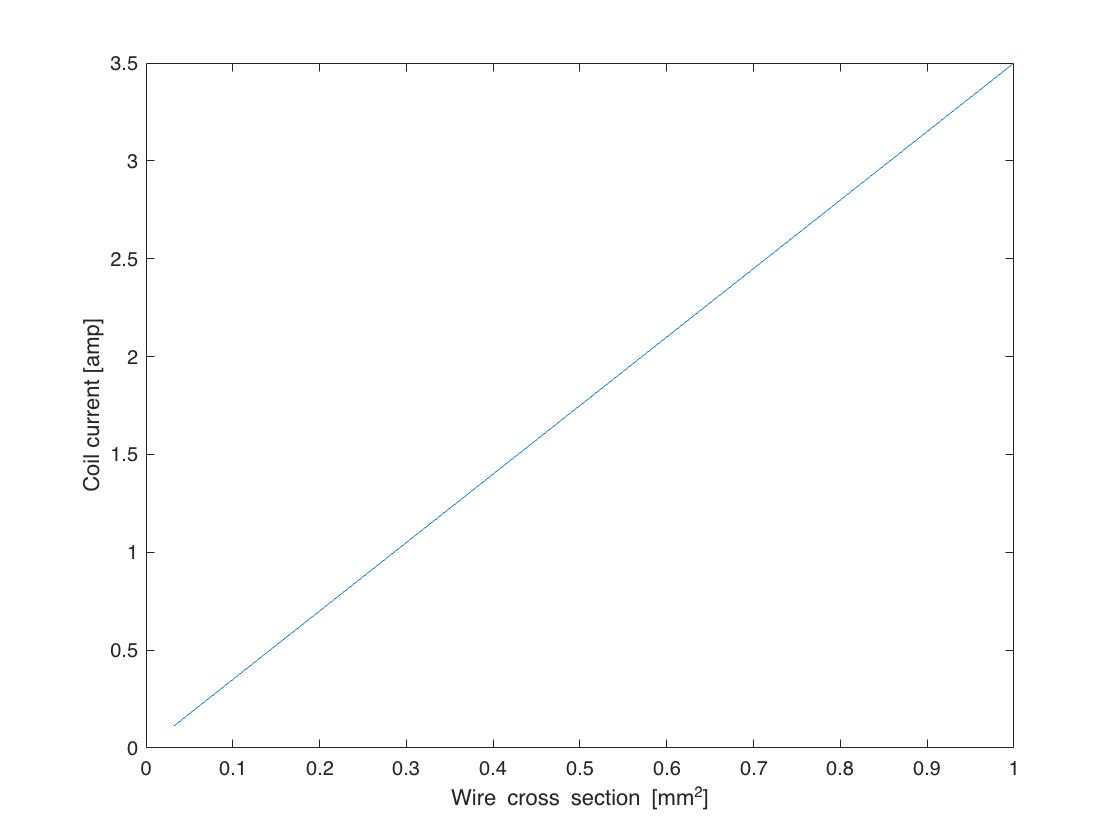

plot(wire_areas,sol_P./sol_V), xlabel('Wire cross section [mm^2]'), ylabel('Coil current [amp]')

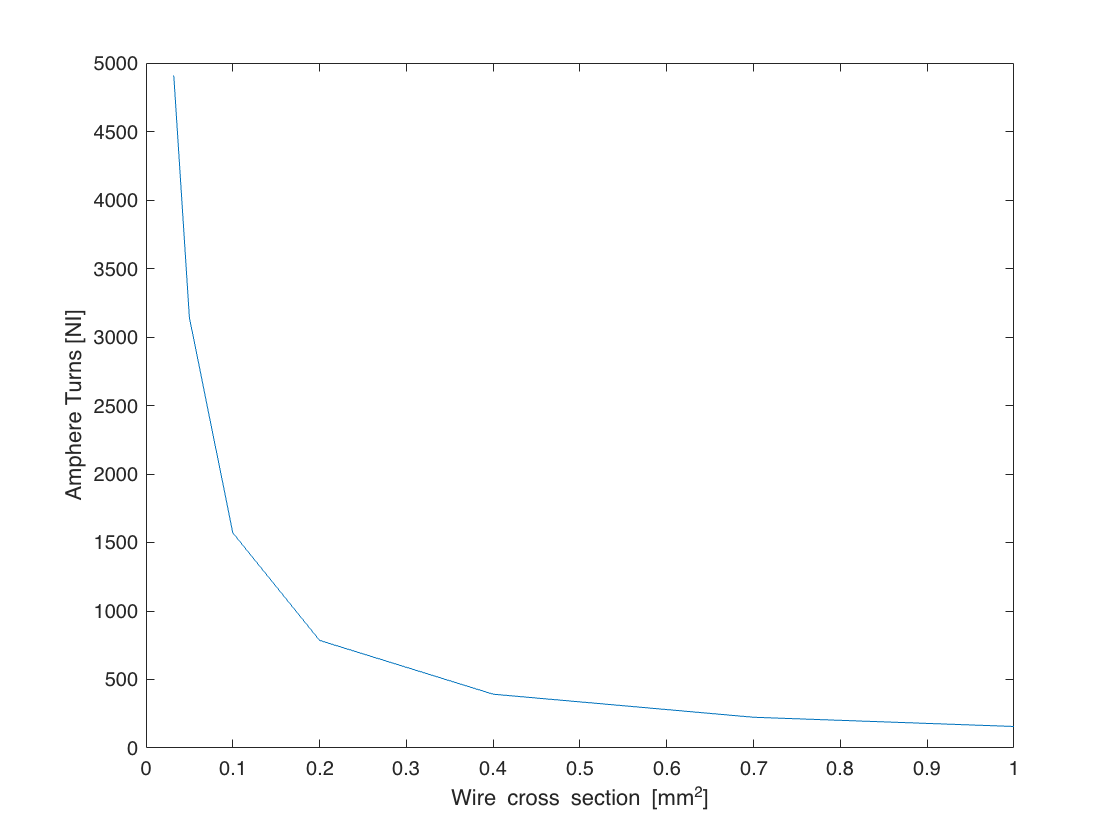

plot(wire_areas,N), xlabel('Wire cross section [mm^2]'), ylabel('Amphere Turns [NI]')

plot(wire_areas,wire_len), xlabel('Wire cross section [mm^2]'), ylabel('Wire Length [m]')

%plot(wire_areas,wire_R), xlabel('Wire cross section [mm^2]'), ylabel('Wire Resistance [Ohm]')

0.05 mm^2 = 30AWG wire.

## Dynamic model

% F = 0.5 * flux^2 / (Area * perm_air)
% N * i = R * flux
% L = N * flux / i
% V = L * di/dt + R * i
% tao = L / R
% V_L(t) = V * e ^ - t / tao
% I(t) = V / R * (1 - e ^ -t / tao)
wire_index = 2;
V = sol_V(wire_index) % source Voltage

V = 17.6706

R = wire_R(wire_index)

R = 100.9747

dt = 1e-6

dt = 1.0000e-06

tao = L(wire_index) / wire_R(wire_index)

tao = 0.0097

valve.wire_area = wire_areas(wire_index);

clearvars t V_L I Fmag sol_V sol_P L
for i=1:ceil(5*tao/dt)
    t(i) = dt * (i-1) * 1e3;
    V_L(i) = V * exp(-i*dt/tao);
    I(i) = V/R *(1 - exp(-i*dt/tao)) * 1e3;
    [Fmag(i),N,wire_len,wire_R,sol_V(i),sol_P(i),L(i)] = valve_magnetic_force(valve,valve.rom,I(i)*1e-3);
end
tao3index = ceil(3*tao/dt);
t(tao3index)

ans = 29.1510

plot(t,Fmag,t(tao3index),Fmag(tao3index),'r*'), xlabel('Time [ms]'), ylabel('Force [N]'), grid on, grid minor

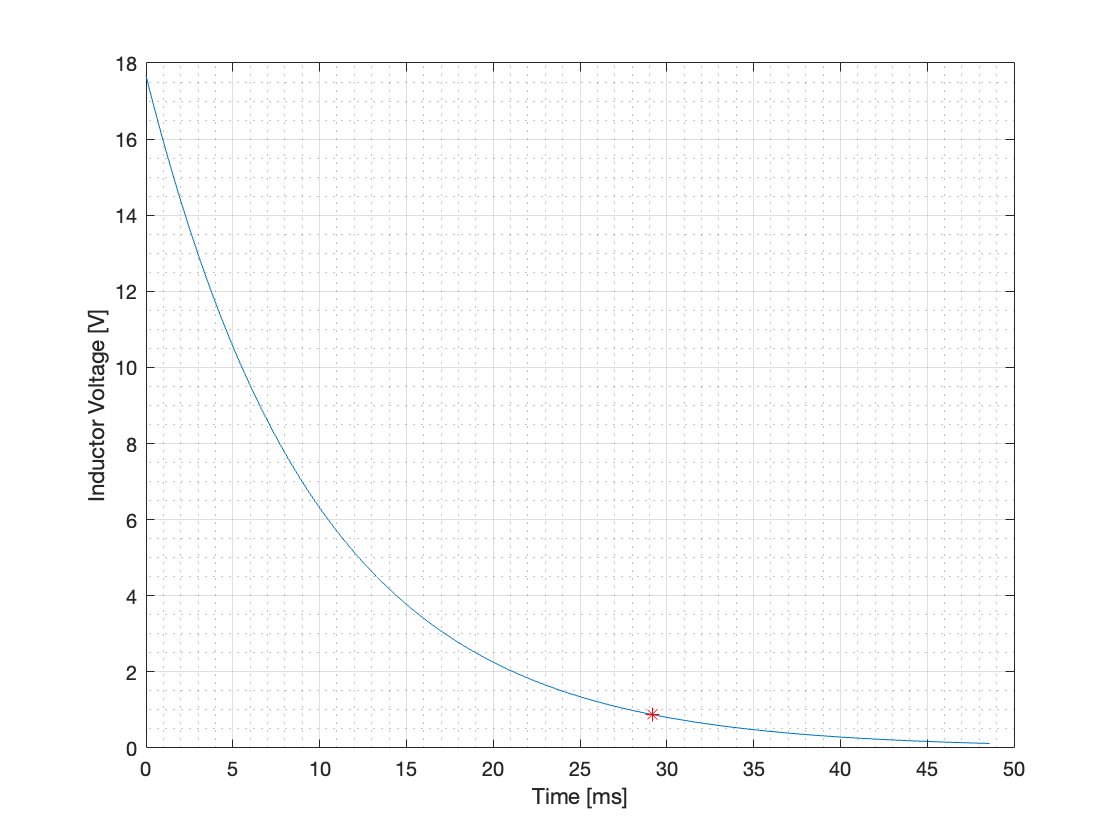

plot(t,V_L,t(tao3index),V_L(tao3index),'r*'), xlabel('Time [ms]'), ylabel('Inductor Voltage [V]'), grid on, grid minor

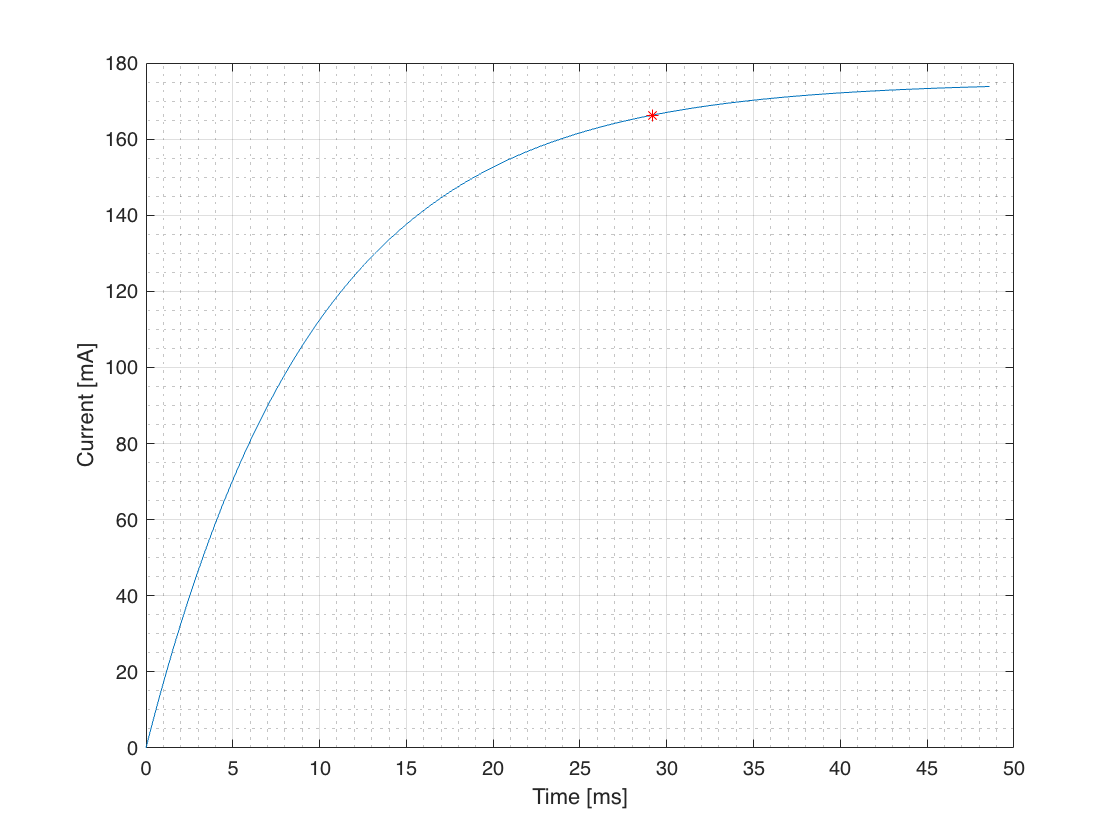

plot(t,I,t(tao3index),I(tao3index),'r*'), xlabel('Time [ms]'), ylabel('Current [mA]'), grid on, grid minor